### Global Variables

prec = 100;
digits(prec);

### Tests

#### `Single Fock and Single Position Function with x = 1.0`

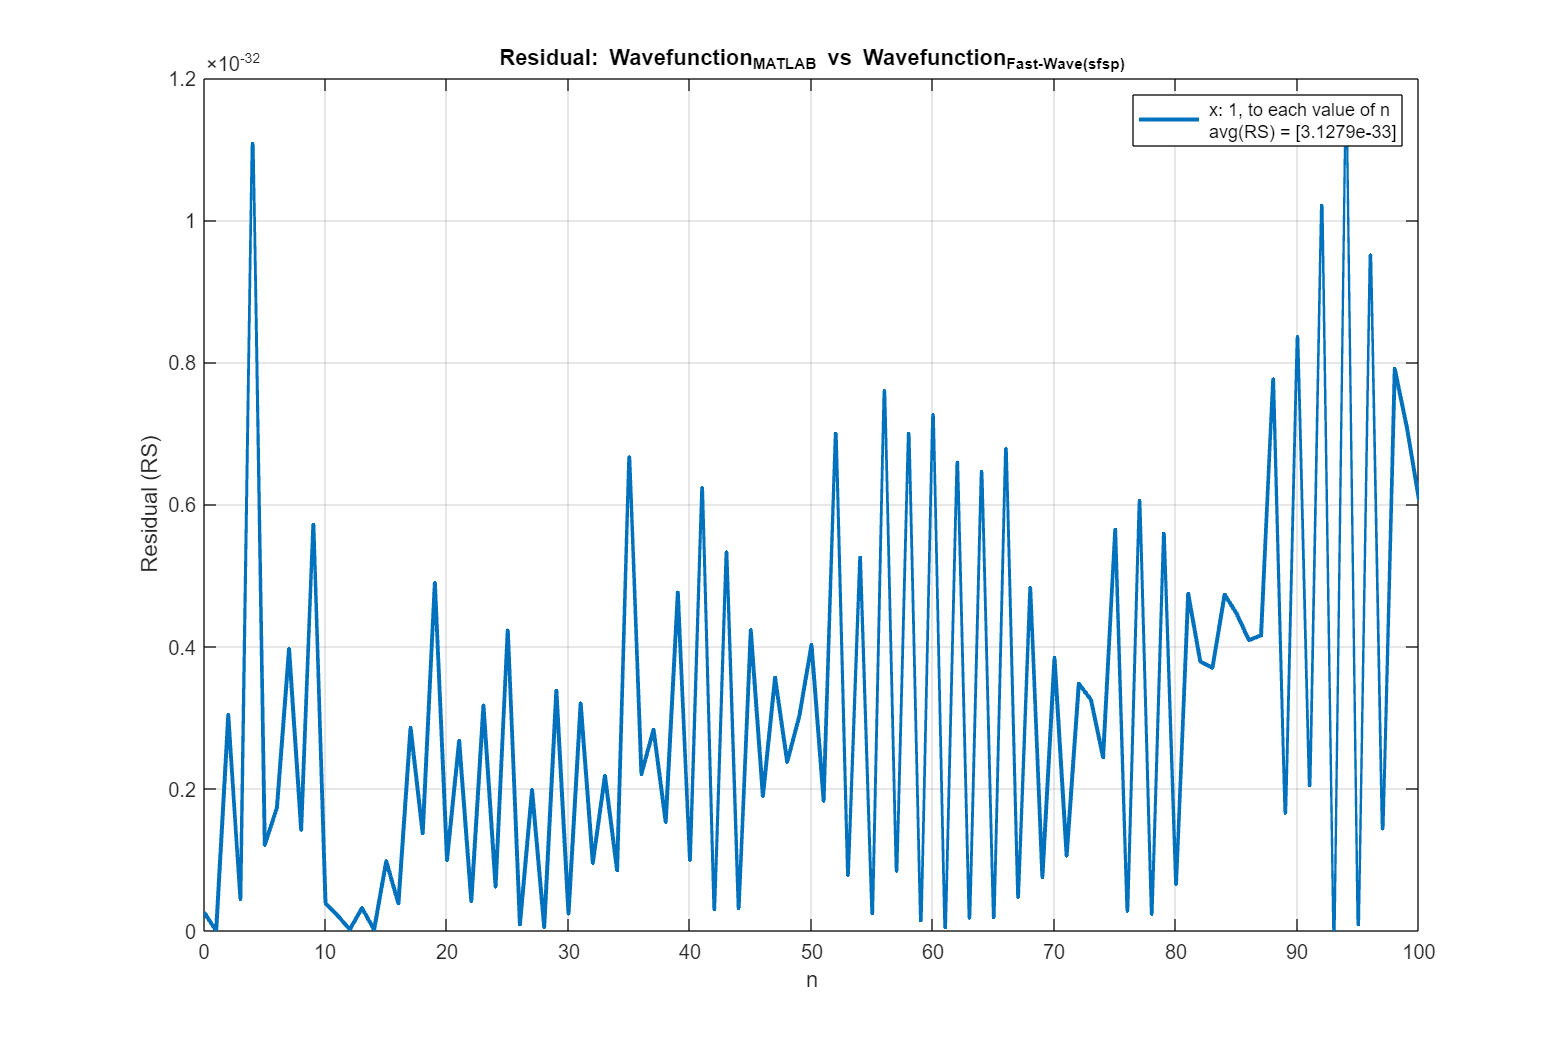

import py.fast_wave.wavefunction_cython.psi_n_single_fock_single_position

N_max = 100;
x = 1.0;

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual(index,:) = (wavefunction_MATLAB_1(index-1, x, prec) - vpa(psi_n_single_fock_single_position(uint64(index-1), x)))^2;
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf(' x: ' + string(x)+', to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(sfsp)}');

#### `Single Fock and Single Position Function with x = 10.0`

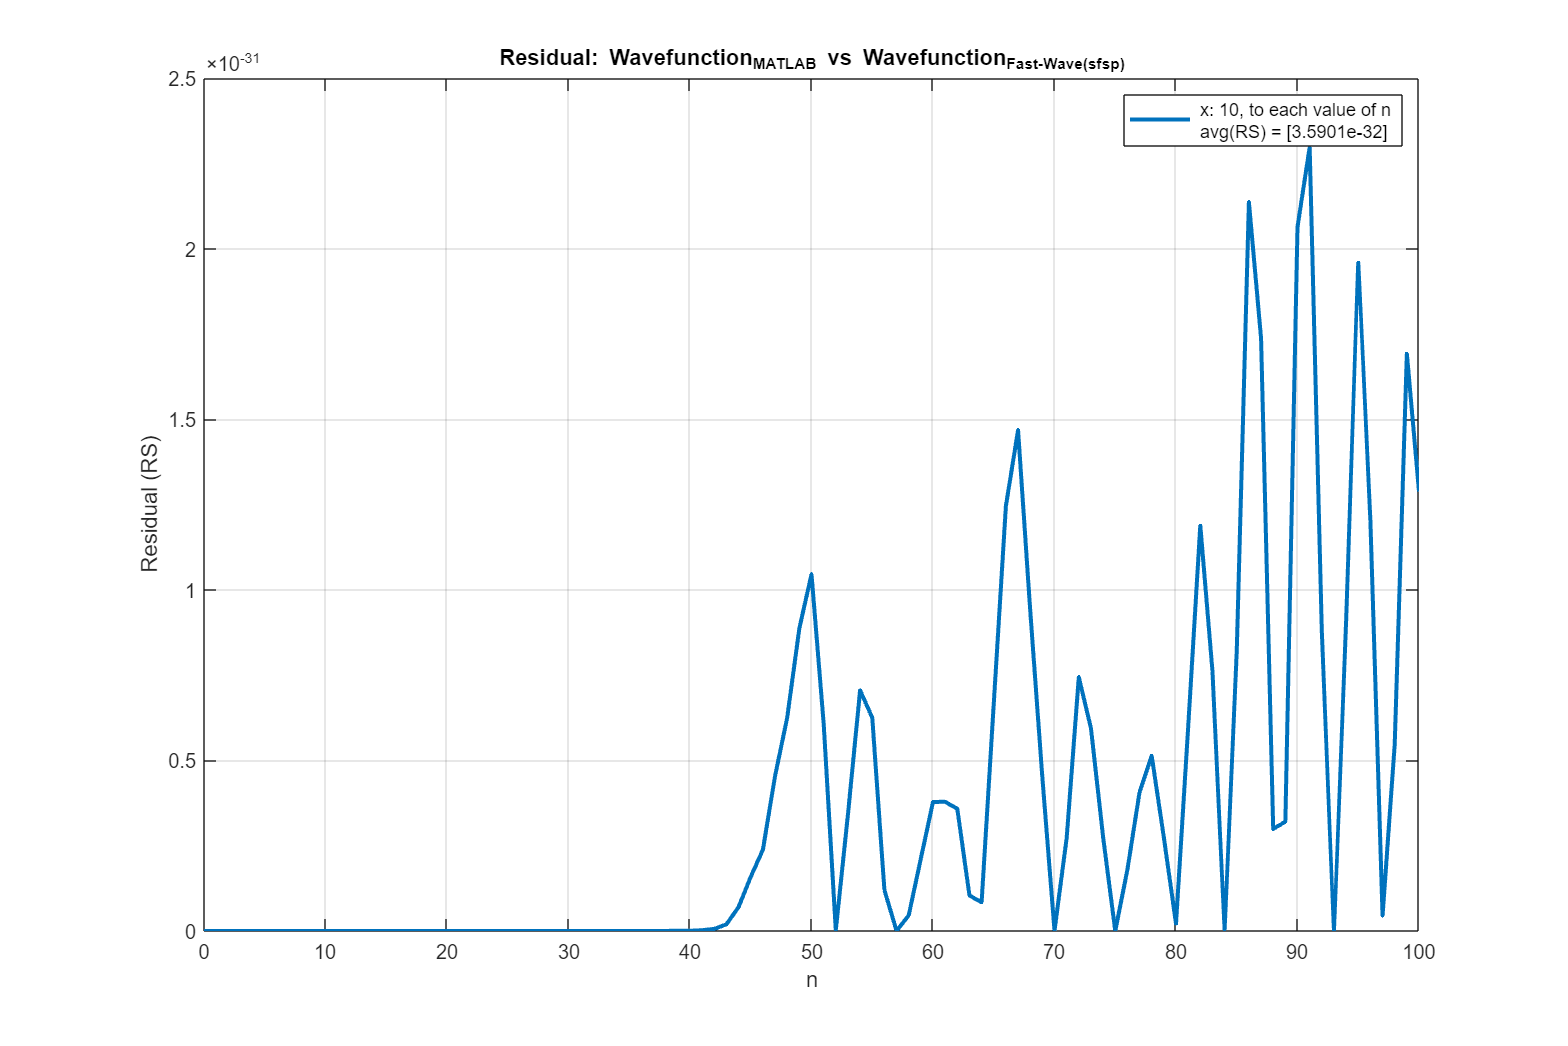

import py.fast_wave.wavefunction_cython.psi_n_single_fock_single_position

N_max = 100;
x = 10.0;

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual(index,:) = (wavefunction_MATLAB_1(index-1, x, prec) - vpa(psi_n_single_fock_single_position(uint64(index-1), x)))^2;
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf(' x: ' + string(x)+', to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(sfsp)}');

#### `Single Fock and Single Position Function with x = 20.0`

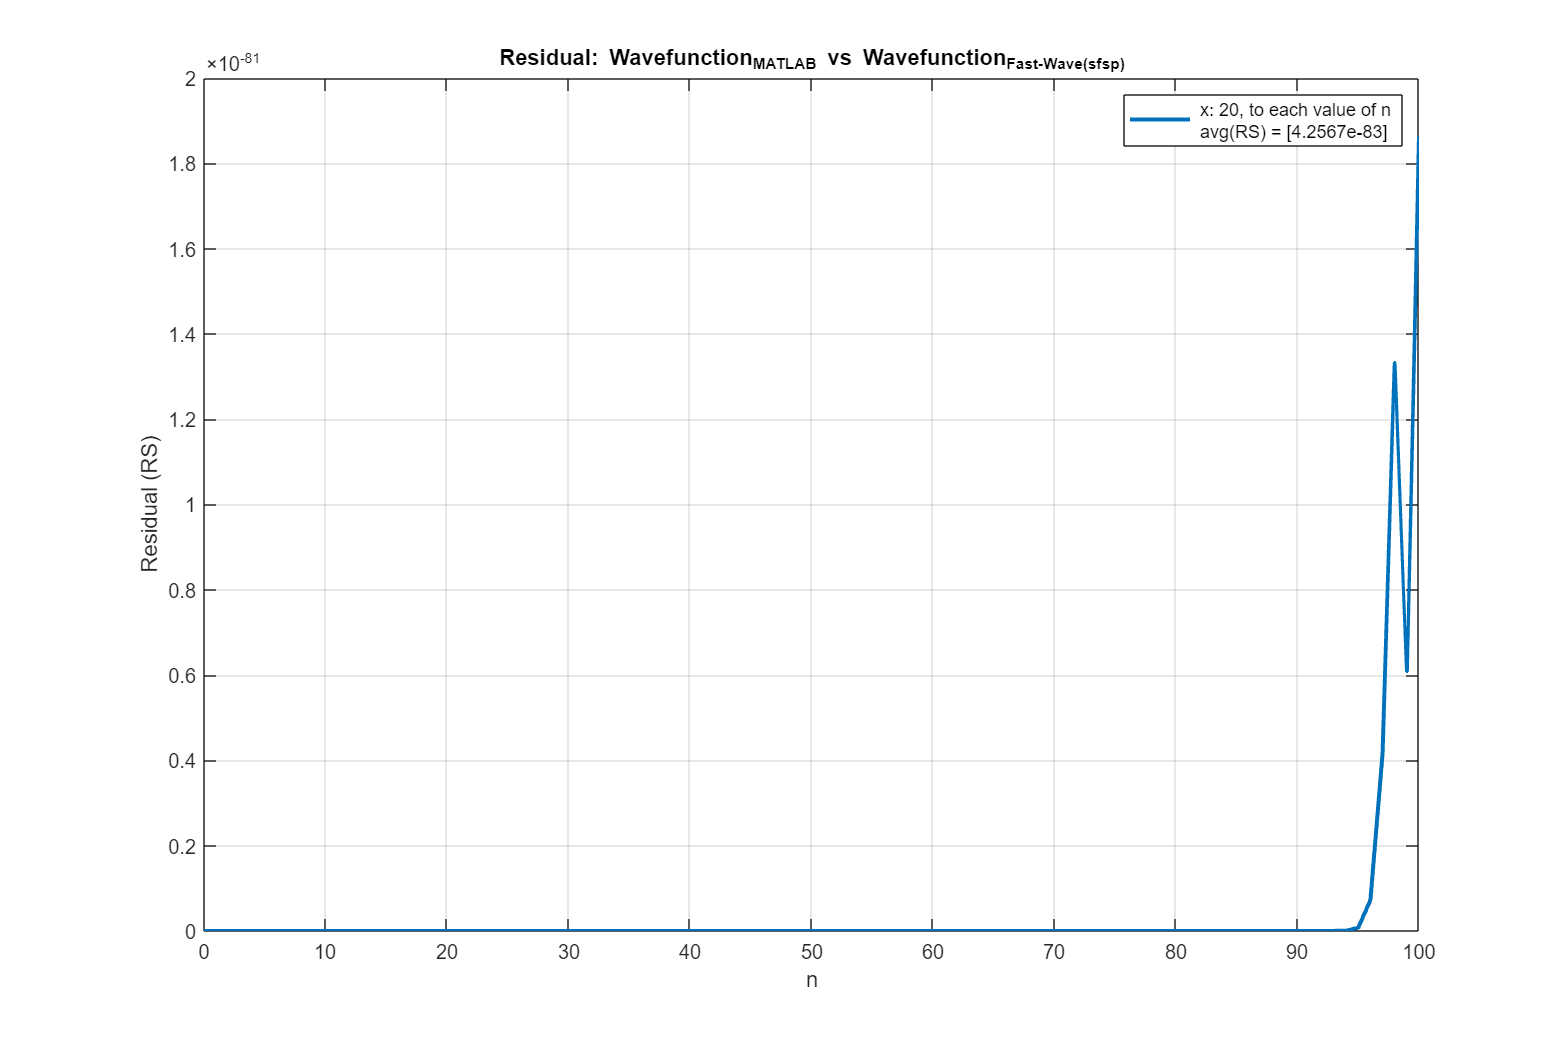

import py.fast_wave.wavefunction_cython.psi_n_single_fock_single_position

N_max = 100;
x = 20.0;

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual(index,:) = (wavefunction_MATLAB_1(index-1, x, prec) - vpa(psi_n_single_fock_single_position(uint64(index-1), x)))^2;
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf(' x: ' + string(x)+', to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(sfsp)}');

#### `Single Fock and Multiple Position Function with X: [(-20)`$\rightarrow$`20; 100]`

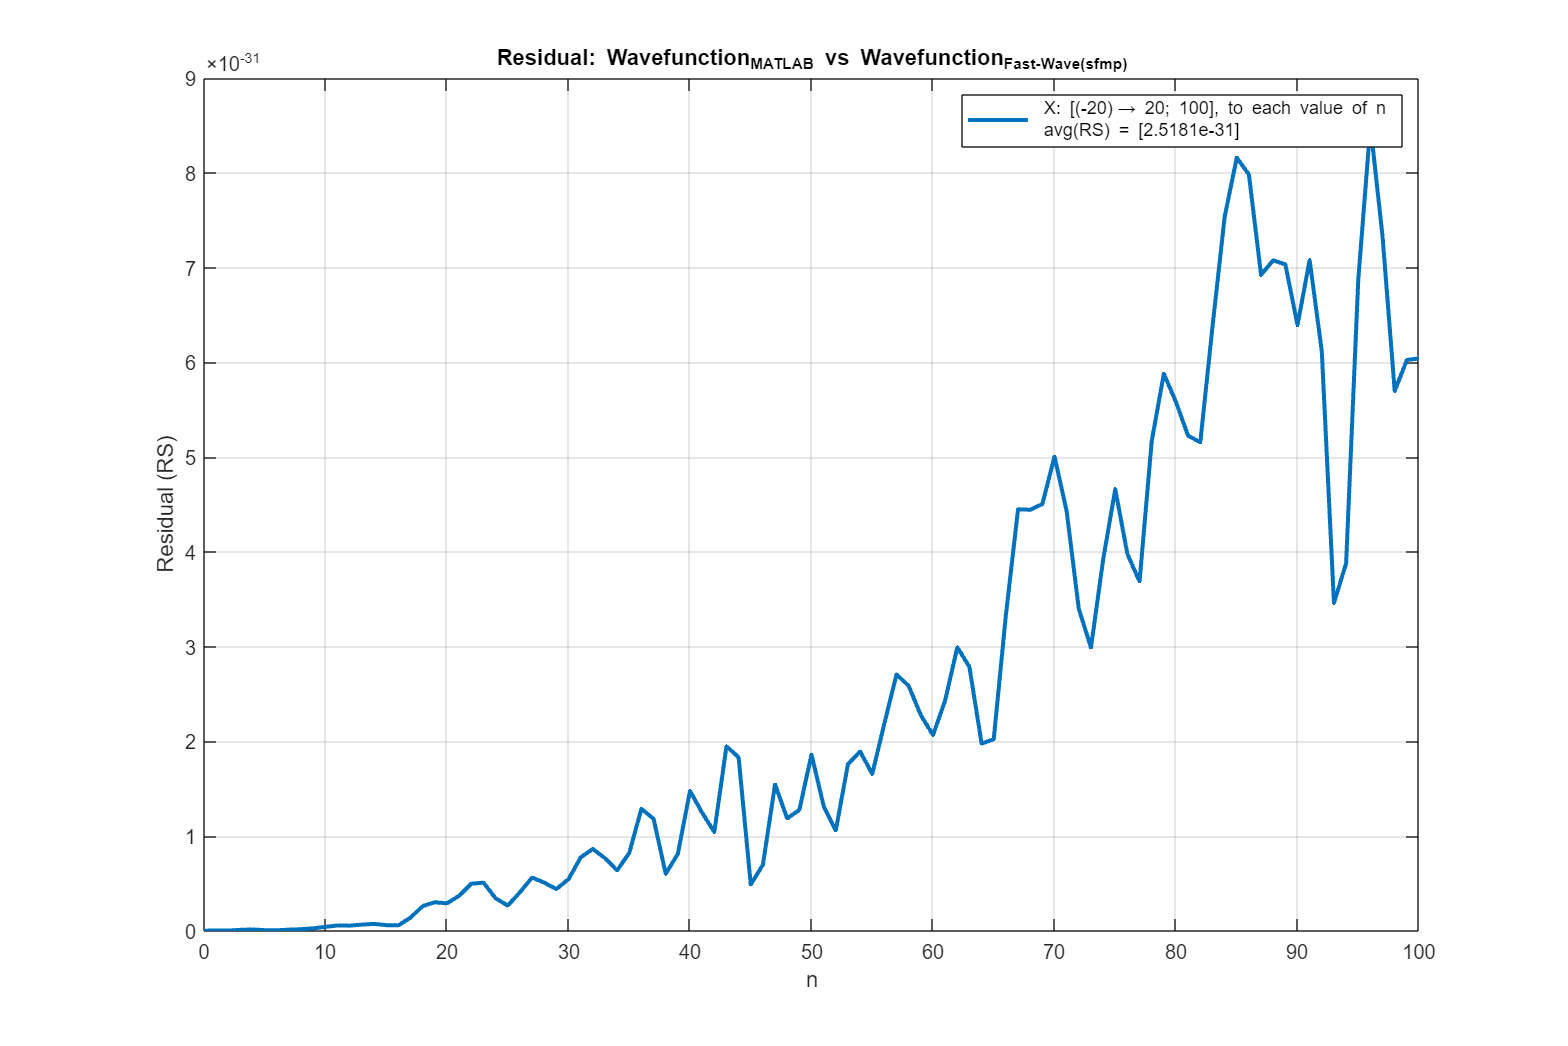

import py.fast_wave.wavefunction_cython.psi_n_single_fock_multiple_position

N_max = 100;
x_max = 20.0;
x_min = -20.0;
x_size = 100;
X = linspace(x_max,x_min,x_size);

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual(index,:) = mean((wavefunction_MATLAB_1(index-1, X, prec) - vpa(double(psi_n_single_fock_multiple_position(uint64(index-1), ...
        py.numpy.array(X))))).^2);
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf(' X: [(-20)\\rightarrow 20; 100], to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(sfmp)}');

#### `Multiple Fock and Single Position Function with x: 1.0`

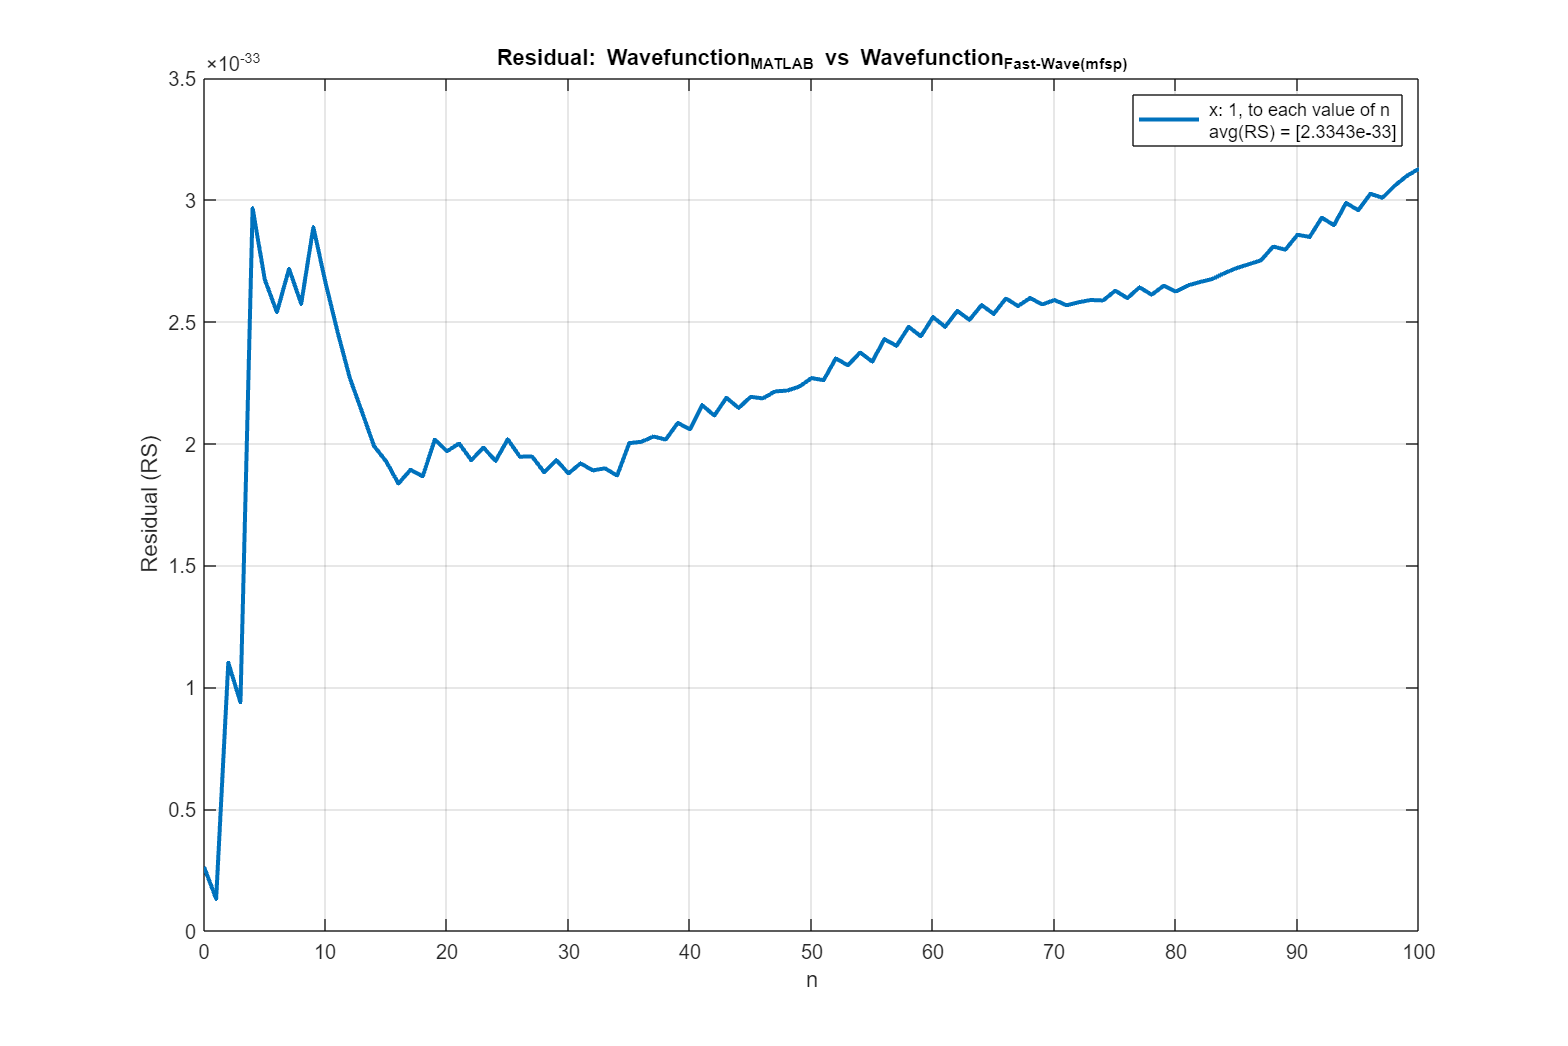

import py.fast_wave.wavefunction_cython.psi_n_multiple_fock_single_position

N_max = 100;
x = 1.0;

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual(index,:) = mean((wavefunction_MATLAB_3(index-1, x, prec) - vpa(double(psi_n_multiple_fock_single_position(uint64(index-1), x)))).^2);
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf(' x: '+string(x)+', to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(mfsp)}');

#### `Multiple Fock and Single Position Function with x = 10.0`

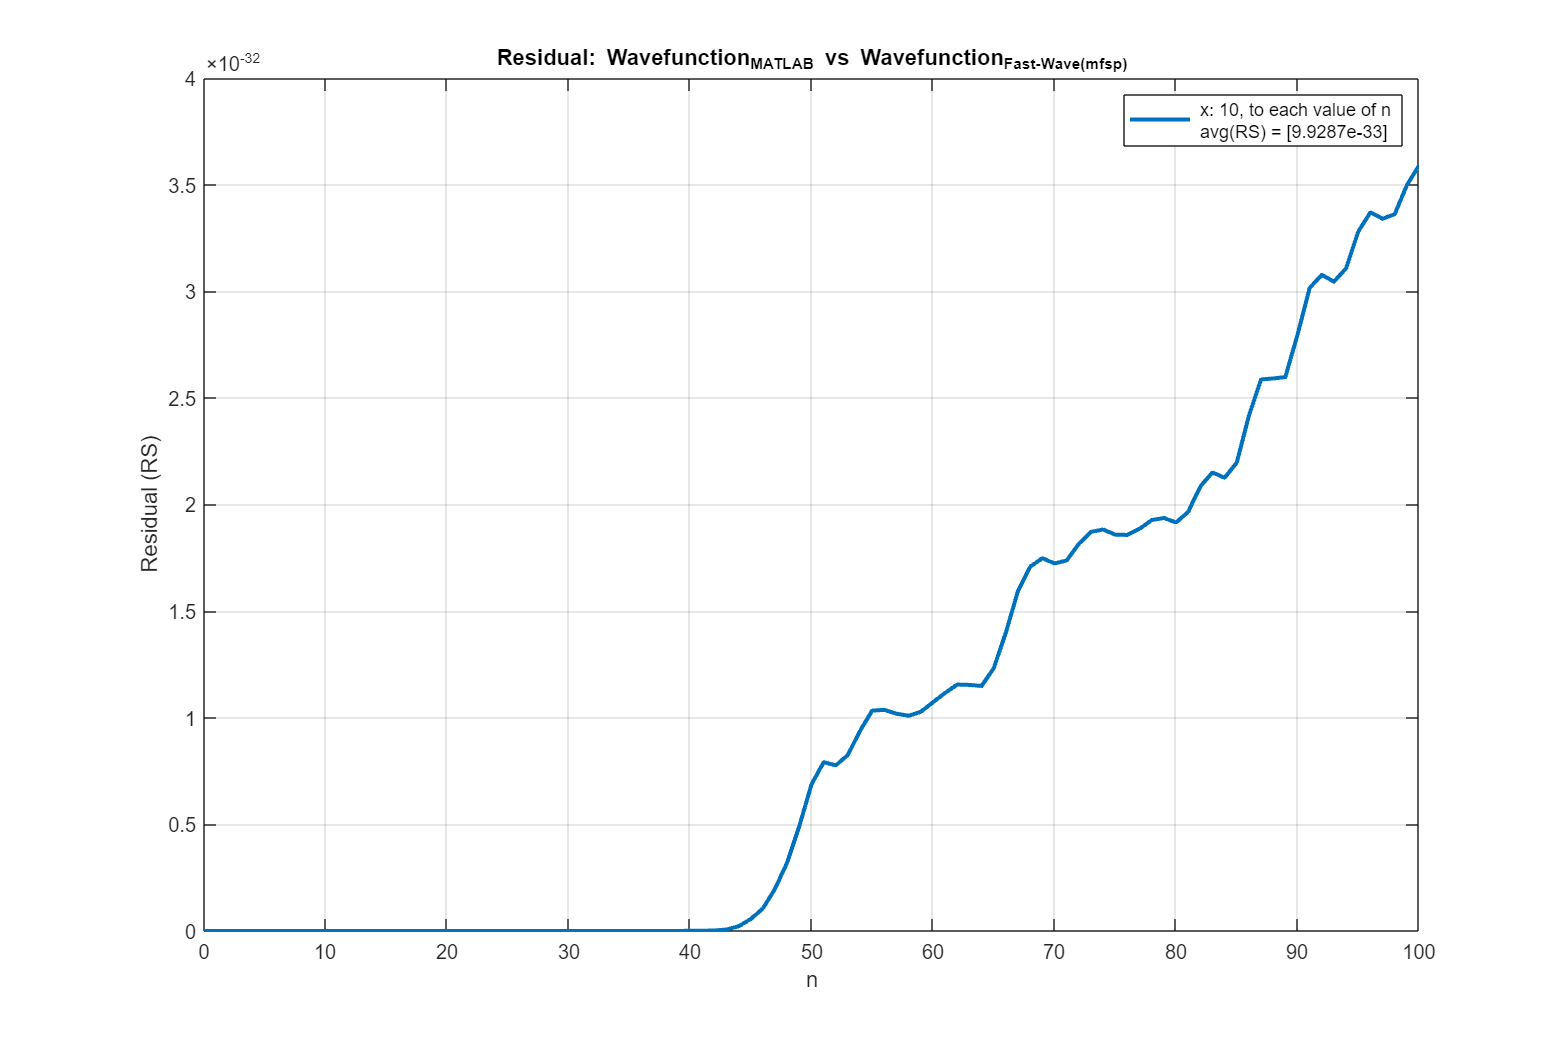

import py.fast_wave.wavefunction_cython.psi_n_multiple_fock_single_position

N_max = 100;
x = 10.0;

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual(index,:) = mean((wavefunction_MATLAB_3(index-1, x, prec) - vpa(double(psi_n_multiple_fock_single_position(uint64(index-1), x)))).^2);
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf(' x: '+string(x)+', to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(mfsp)}');

#### `Multiple Fock and Single Position Function with x = 20.0`

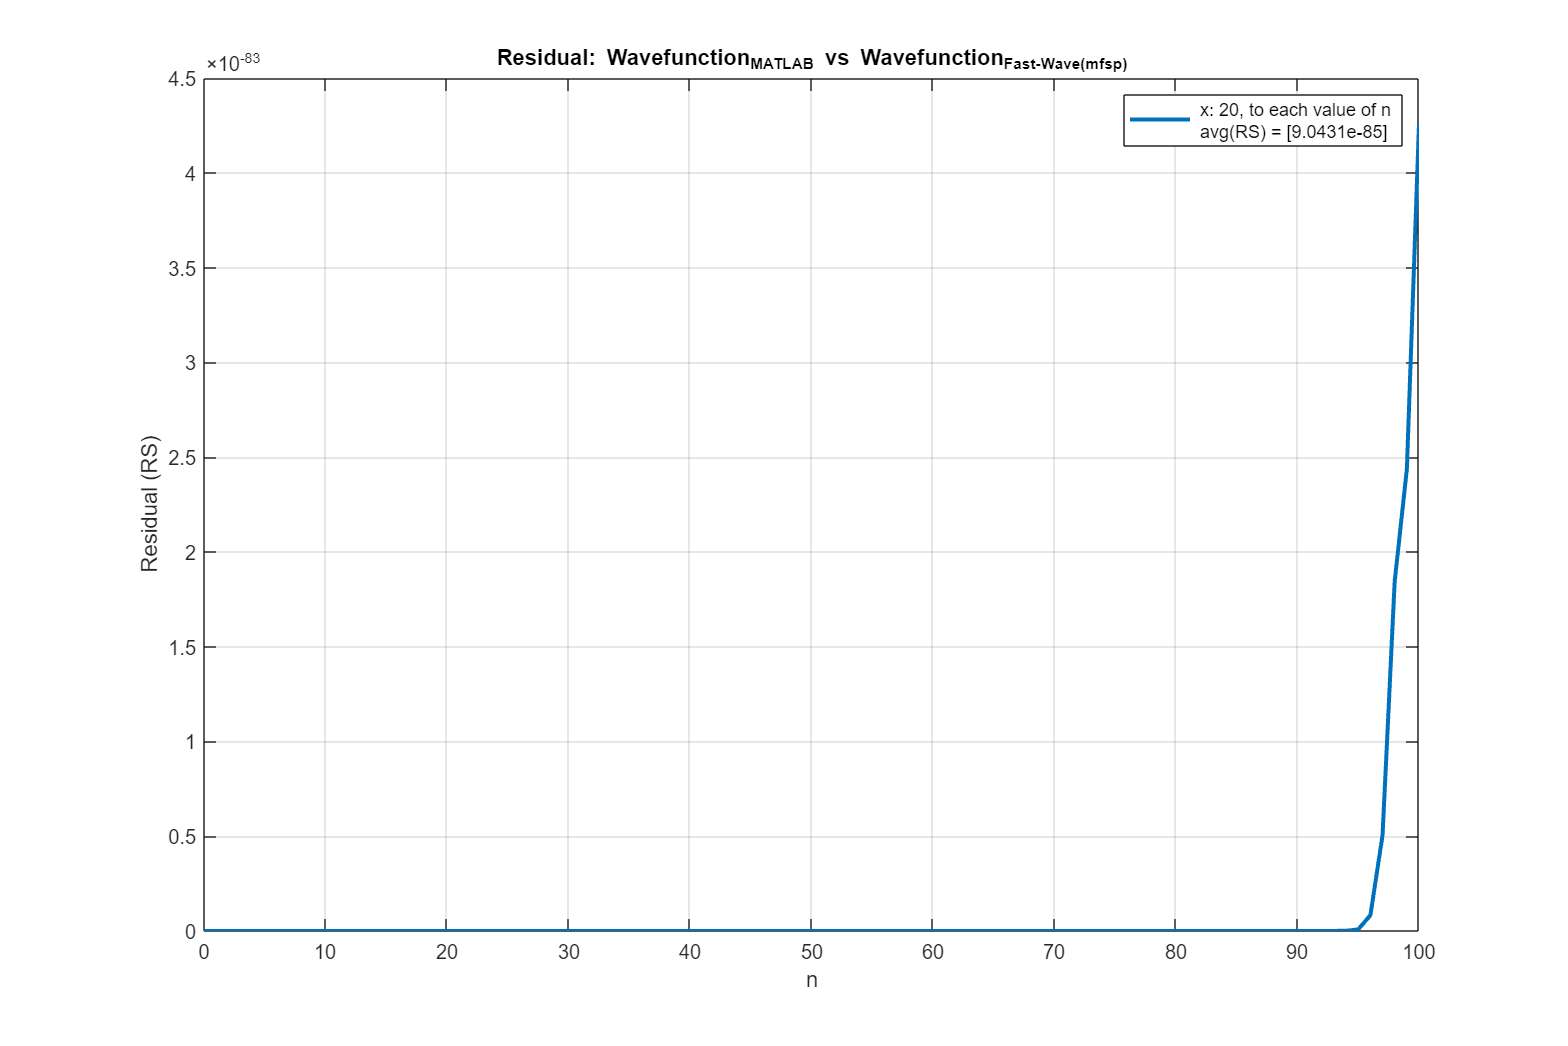

import py.fast_wave.wavefunction_cython.psi_n_multiple_fock_single_position

N_max = 100;
x = 20.0;

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual(index,:) = mean((wavefunction_MATLAB_3(index-1, x, prec) - vpa(double(psi_n_multiple_fock_single_position(uint64(index-1), x)))).^2);
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf(' x: '+string(x)+', to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(mfsp)}');

#### `Multiple Fock and Multiple Position Function with X: [(-20)`$\rightarrow$`20; 100]`

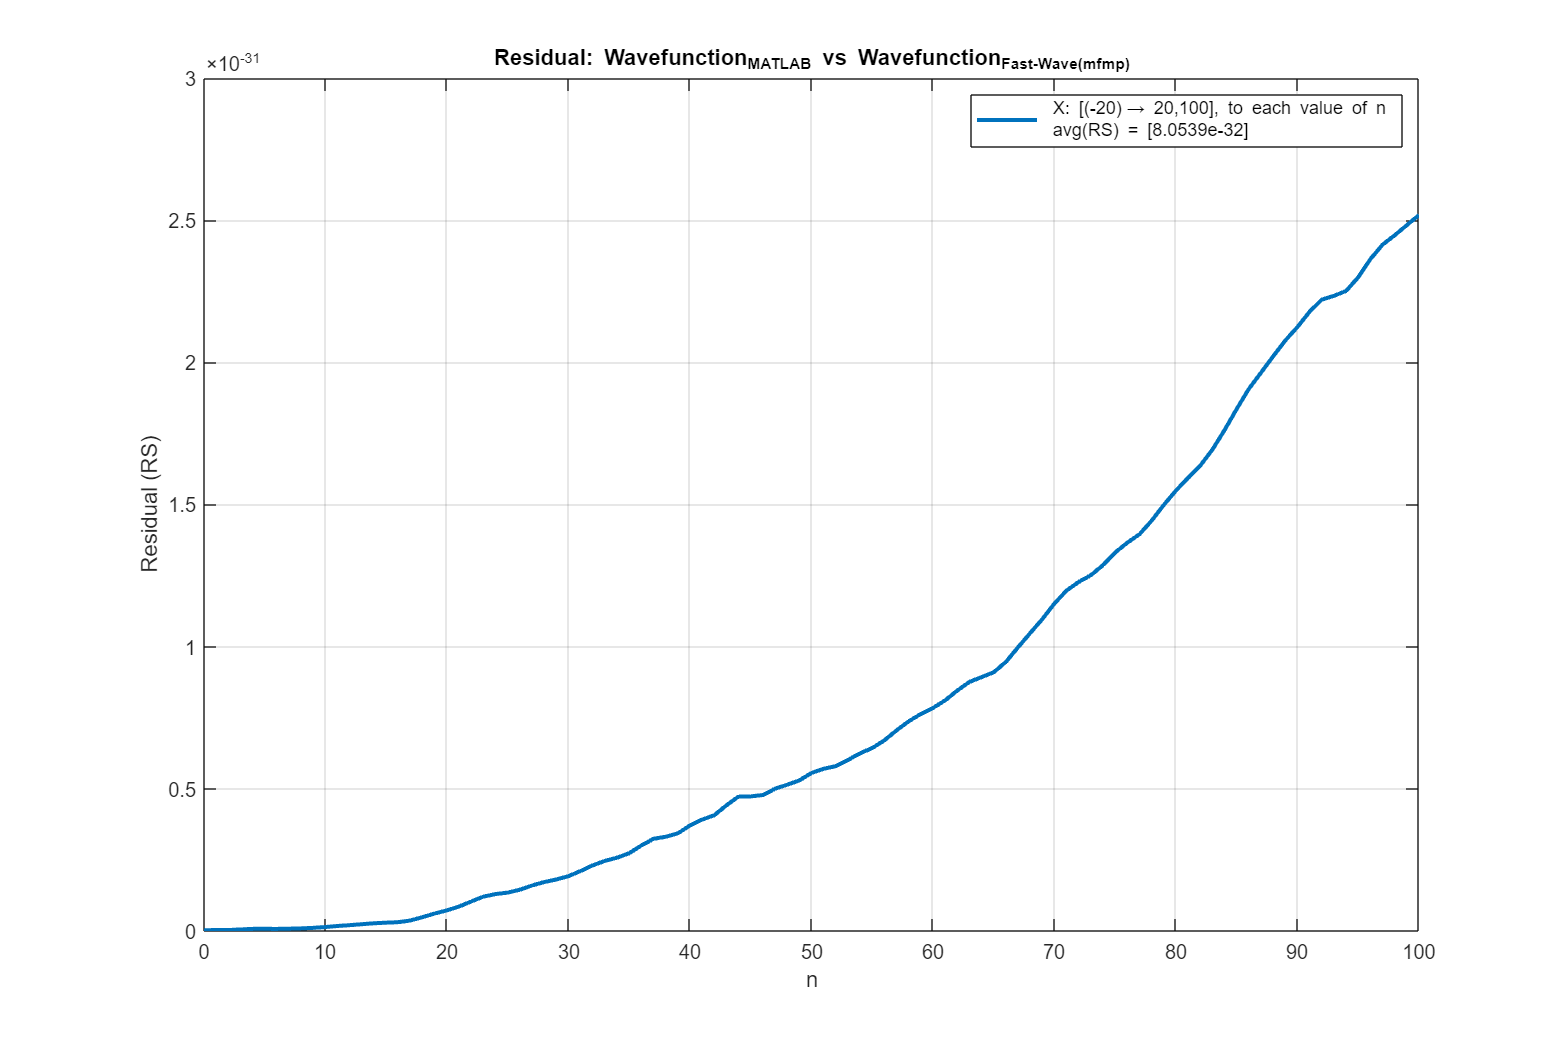

import py.fast_wave.wavefunction_cython.psi_n_multiple_fock_multiple_position

N_max = 100;
x_max = 20.0;
x_min = -20.0;
x_size = 100;
X = linspace(x_max,x_min,x_size);

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual_Matrix = ( wavefunction_MATLAB_4(index-1, X, prec) - vpa(double(psi_n_multiple_fock_multiple_position(uint64(index-1), py.numpy.array(X)))) ).^2;
    Residual(index,:) = mean(Residual_Matrix(:));
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf(' X: [(-20)\\rightarrow 20,100], to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(mfmp)}');